# Task 2

**Resources**

- [https://www.weather.gov/documentation/services-web-api](https://www.weather.gov/documentation/services-web-api)

- [https://api.weather.gov/points/42.2813,-71.355](https://api.weather.gov/points/42.2813,-71.355)

- [https://api.weather.gov/gridpoints/BOX/62,85/forecast/hourly](https://api.weather.gov/gridpoints/BOX/62,85/forecast/hourly)

## **Get weather from web service**

jason = webread("https://api.weather.gov/gridpoints/BOX/62,85/forecast/hourly");
% pol = jason.geometry.coordinates; geoscatter(pol(:,:,1),pol(:,:,2))

## Build Timetable

T = struct2table(jason.properties.periods);
time = datetime(T.startTime,"InputFormat","uuuu-MM-dd'T'HH:mm:ssssZZZZZ","TimeZone","America/New_York");
temperature = T.temperature;
TT = timetable(time,temperature)

TT = 156x1 timetable
            time            temperature
    ____________________    ___________

    29-Apr-2024 18:00:00        67     
    29-Apr-2024 19:00:00        65     
    29-Apr-2024 20:00:00        62     
    29-Apr-2024 21:00:00        60     
    29-Apr-2024 22:00:00        57     
    29-Apr-2024 23:00:00        56     
    30-Apr-2024 00:00:00        55     
    30-Apr-2024 01:00:00        55     
    30-Apr-2024 02:00:00        54     
    30-Apr-2024 03:00:00        53     
    30-Apr-2024 04:00:00        53     
    30-Apr-2024 05:00:00        52     
    30-Apr-2024 06:00:00        50     
    30-Apr-2024 07:00:00        49     
    30-Apr-2024 08:00:00

## Plot data over time

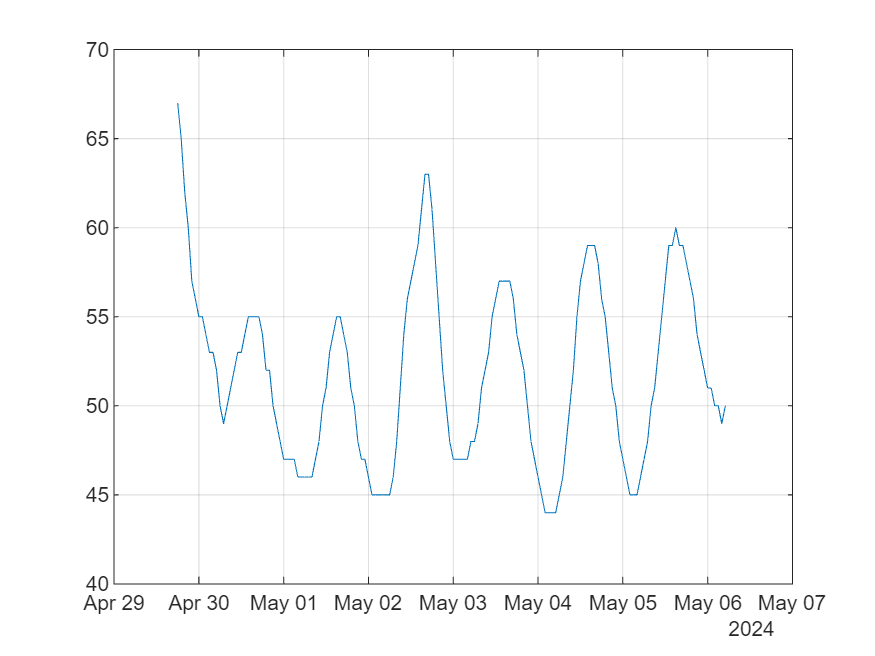

plot(TT.time,TT.temperature)
grid on

## **Export data**

writetimetable(TT,'Data/natick.csv')

## **Create reports**

export('Tasks/task2.mlx','Reports/task2.md');
export('Tasks/task2.mlx','Reports/task2.ipynb');
export('Tasks/task2.mlx','Reports/task2.docx');
export('Tasks/task2.mlx','Reports/task2.pdf');
export('Tasks/task2.mlx','Reports/task2.html');